Problem 1

mu_Earth = 398600.4415;
mu = mu_Earth;
R_Earth = 6378.1363;
p = 6*R_Earth;
e = 0.6;
theta_astrix = 90; %degrees

a = p/(1-e^2)

a = 5.9795e+04

r_p = p/(1+e)

r_p = 2.3918e+04

r_a = p/(1-e)

r_a = 9.5672e+04

period = 2*pi*sqrt(a^3/mu)

period = 1.4552e+05

period/(3600)

ans = 40.4209

epsilon = -mu/(2*a)

epsilon = -3.3331

r_0 = p

r_0 = 3.8269e+04

v_0 = sqrt(2*(epsilon+mu/r_0))

v_0 = 3.7637

E_0 = rad2deg(acos((a-r_0)/(a*e)))

E_0 = 53.1301

gamma_0 = rad2deg(acos(sqrt(mu*p)/(r_0*v_0)))

gamma_0 = 30.9638

v_c0 = sqrt(mu/r_0)

v_c0 = 3.2274

sqrt(2)*v_c0

ans = 4.5642

r_0_vec = r_0*[cos(deg2rad(theta_astrix)), sin(deg2rad(theta_astrix))]

r_0_vec = 	1.0e+04 *

    0.0000    3.8269


v_0_vec = v_0*[cos(deg2rad(gamma_0)), sin(deg2rad(gamma_0))].*[-1,1]

v_0_vec =    -3.2274    1.9364


E_f = 225; %degrees
r_f = a*(1-e*cos(deg2rad(E_f)))

r_f = 8.5164e+04

v_f = sqrt(2*(epsilon+mu/r_f))

v_f = 1.6415

rad2deg(atan(2*sqrt((1+e)/(1-e))*tan(deg2rad(E_f/2))))

ans = -84.0879

theta_f = 360-acosd(p/(e*r_f)-1/e)

theta_f = 203.4018

gamma_f = acosd(sqrt(mu*p)/(r_f*v_f))

gamma_f = 27.9384

r_f_vec = r_f*[cosd(theta_f), sind(theta_f)]

r_f_vec = 	1.0e+04 *

   -7.8158   -3.3825


theta_f+90-gamma_f

ans = 265.4635

v_f_vec = v_f*[cosd(theta_f+90+gamma_f), sind(theta_f+90+gamma_f)]

v_f_vec =     1.2818   -1.0255


t_o_diff = (deg2rad(E_0)-e*sind(E_0))/sqrt(mu/a^3)

t_o_diff = 1.0359e+04

t_f_diff = (deg2rad(E_f)-e*sind(E_f))/sqrt(mu/a^3)

t_f_diff = 1.0077e+05

TOF = t_f_diff-t_o_diff

TOF = 9.0414e+04

TOF/3600/24

ans = 1.0465

d_theta = theta_f-theta_astrix

d_theta = 113.4018

d_E = E_f-E_0

d_E = 171.8699

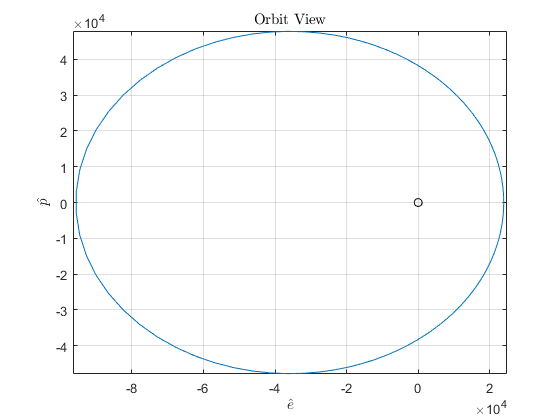

plot_orbit(e,p)

Problem 3

r_p = R_Earth+225;
v_c = sqrt(mu/r_p)

v_c = 7.7695

v_escape = sqrt(2)*v_c

v_escape = 10.9877

delta_V_percent = (v_escape-v_c)/v_c*100

delta_V_percent = 41.4214

p = 2*r_p;
r_list = [2*R_Earth, 10*R_Earth, 75*R_Earth, 200*R_Earth, 800*R_Earth, 420*R_Earth];
v_list = sqrt(2*mu./r_list)

v_list =     7.9054    3.5354    1.2909    0.7905    0.3953    0.5455


theta_list = acosd(p./r_list-1)

theta_list =    87.9784  142.4616  166.5056  171.7483  175.8768  174.3084



t_diff_list = 1/6*sqrt(p^3/mu)*(tand(theta_list/2).^3+3*tand(theta_list/2))/(3600*24)

t_diff_list =     0.0176    0.1591    2.9178   12.5471   99.7995   38.0299


gamma_list = acosd((1+cosd(theta_list))./sqrt(2+2*cosd(theta_list)))

gamma_list =    43.9892   71.2308   83.2528   85.8742   87.9384   87.1542


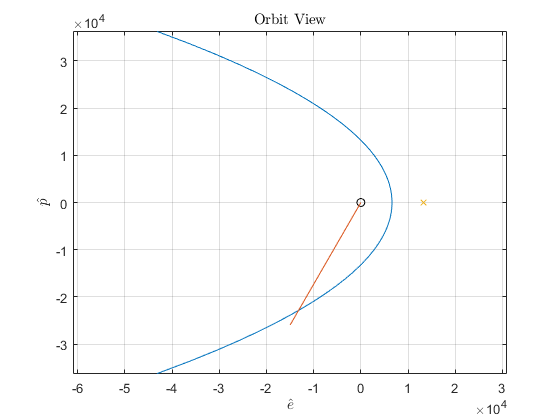

plot_orbit(1,p)
plot([0,3e4*cosd(-120)],[0,3e4*sind(-120)]);hold on;
plot(2*r_p,0,"x")

r_1 = p/(1+cosd(120))

r_1 = 2.6413e+04

v_1 = sqrt(2*mu/r_1)

v_1 = 5.4939

gamma = acosd((1+cosd(120))/sqrt(2+2*cosd(120)))

gamma = 60.0000

acosd(sqrt(mu*p)/(r_1*v_1))

ans = 60.0000

mu/r_list(3)^2

ans = 1.7419e-06

Problem 4

R_Moon = 1738.2;
mu_Moon = 4902.8005821478;
a_abs = 7050;
theta_0 = -60;
r_p = R_Moon + 800

r_p = 2.5382e+03

v_p = sqrt(2*mu_Moon/r_p+mu_Moon/a_abs)

v_p = 2.1351

e = 1+r_p/a_abs

e = 1.3600

p = a_abs*(e^2-1)

p = 5.9902e+03

b = a_abs*sqrt(e^2-1)

b = 6.4985e+03

h = sqrt(p*mu_Moon)

h = 5.4193e+03

delta = asind(1/e)*2

delta = 94.6616

v_inf = sqrt(mu_Moon/a_abs)

v_inf = 0.8339

epsilon = mu_Moon/(2*a_abs)

epsilon = 0.3477

r_0 = p/(1+e*cosd(theta_0))

r_0 = 3.5656e+03

v_0 = sqrt(2*mu_Moon/r_0+mu_Moon/a_abs)

v_0 = 1.8562

gamma_0 = acosd(sqrt(mu_Moon*p)/(r_0*v_0))

gamma_0 = 35.0334

acosd((1+e*cosd(theta_0))/sqrt(1+e^2+2*e*cosd(theta_0)))

ans = 35.0334

H = acosh(r_0/a_abs/e+1/e)

H = 0.4589

rad2deg(H)

ans = 26.2924

t2perilune = (e*sinh(H)-H)/(sqrt(mu_Moon/a_abs^3))

t2perilune = 1.5838e+03

r_2 = p/(1+e*cosd(100))

r_2 = 7.8423e+03

v_2 = sqrt(2*mu_Moon/r_2+mu_Moon/a_abs)

v_2 = 1.3949

gamma_2 = acosd(sqrt(mu_Moon*p)/(r_2*v_2))

gamma_2 = 60.3041

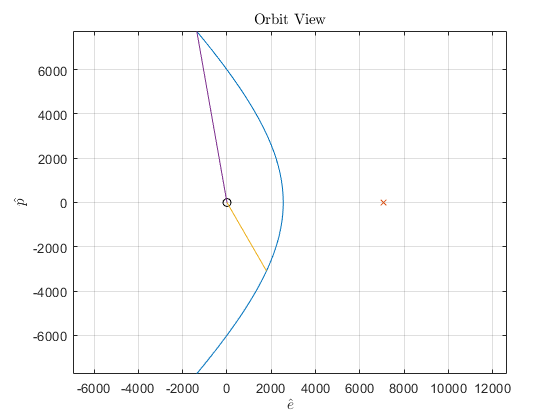

plot_orbit(e,p);hold on;
plot(a_abs,0,'x');
plot([0, r_0*cosd(theta_0)],[0, r_0*sind(theta_0)])
plot([0,r_2*cosd(100)],[0, r_2*sind(100)])